[TBS, selected_RB, selected_MCS] = selectTBSFromFiveSINRs(SINR1, SINR2, SINR3, SINR4, SINR5)

TBS = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


selected_RB = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


selected_MCS = 1×5 cell array
    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}    {1000×1 double}


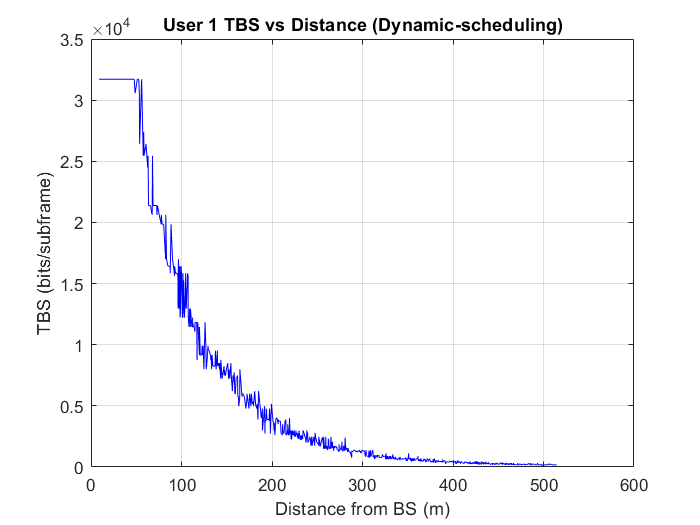

figure; plot(ds, TBS{1}(idx), 'b-'); grid on
xlabel('Distance from BS (m)'); ylabel('TBS (bits/subframe)');
title('User 1 TBS vs Distance (Dynamic-scheduling)');

function [TBS, selected_RB, selected_MCS] = selectTBSFromFiveSINRs(SINR1, SINR2, SINR3, SINR4, SINR5)
    % Takes five inputs (SINR1 to SINR5), which can be scalars or vectors.
    % It processes each element of the inputs and returns cell arrays where each 
    % cell contains a result vector corresponding to the input vector.
    % For example, if SINR1 is a 1000x1 vector, TBS{1} will be a 1000x1 vector.

    % Group the five inputs into a cell array to loop through them
    sinr_inputs_cell = {SINR1, SINR2, SINR3, SINR4, SINR5};

    % Load the predefined TBS table
    tbsTable = createTBS_Table();
    
    % --- Static Definitions ---
    requiredSINR = [-Inf, -25.0, -21.0, -17.0, -13.0, -9.0, -5.0, 0.0, ...
                    2.0, 6.0, 12.0, 16.0, 20.0, 25.0, 30.0, 35.0];
    CQI_MCS_map = 0:14;
    
    % --- Initialize Final Output Cell Arrays ---
    num_users = 5;
    TBS = cell(1, num_users);
    selected_RB = cell(1, num_users);
    selected_MCS = cell(1, num_users);
    
    % --- Outer loop: Iterate through each of the 5 users ---
    for i = 1:num_users
        currentUser_sinr_vector = sinr_inputs_cell{i};
        num_timesteps = length(currentUser_sinr_vector);
        
        % Pre-allocate result vectors for the current user for efficiency
        currentUser_TBS_vector = zeros(size(currentUser_sinr_vector));
        currentUser_RB_vector = zeros(size(currentUser_sinr_vector));
        currentUser_MCS_vector = zeros(size(currentUser_sinr_vector));
        
        % --- Inner loop: Iterate through each SINR value for the current user ---
        for j = 1:num_timesteps
            scalar_sinr = currentUser_sinr_vector(j);
            
            % Apply the original selection logic to the single SINR value
            CQI = find(scalar_sinr >= requiredSINR, 1, 'last');
            if isempty(CQI) || CQI < 1
                CQI = 1;
            elseif CQI > 15
                CQI = 15;
            end
            
            scalar_MCS = CQI_MCS_map(CQI);
            
            if scalar_sinr < -27
                scalar_RB = 1;
            elseif scalar_sinr < -24
                scalar_RB = 2;
            elseif scalar_sinr < -21
                scalar_RB = 3;
            elseif scalar_sinr < -18
                scalar_RB = 4;
            elseif scalar_sinr < -15
                scalar_RB = randi([5 6]);
            elseif scalar_sinr < -12
                scalar_RB = randi([7 8]);
            elseif scalar_sinr < -10
                scalar_RB = randi([9 10]);
            elseif scalar_sinr < -8
                scalar_RB = randi([11 13]);
            elseif scalar_sinr < -6
                scalar_RB = randi([14 16]);
            elseif scalar_sinr < -4
                scalar_RB = randi([17 20]);
            elseif scalar_sinr < -2
                scalar_RB = randi([21 24]);
            elseif scalar_sinr < 0
                scalar_RB = randi([25 28]);
            elseif scalar_sinr < 2
                scalar_RB = randi([29 33]);
            elseif scalar_sinr < 4
                scalar_RB = randi([34 38]);
            elseif scalar_sinr < 6
                scalar_RB = randi([39 44]);
            elseif scalar_sinr < 8
                scalar_RB = randi([45 50]);
            elseif scalar_sinr < 10
                scalar_RB = randi([51 56]);
            elseif scalar_sinr < 12
                scalar_RB = randi([57 62]);
            elseif scalar_sinr < 14
                scalar_RB = randi([63 68]);
            elseif scalar_sinr < 16
                scalar_RB = randi([69 74]);
            elseif scalar_sinr < 18
                scalar_RB = randi([75 80]);
            elseif scalar_sinr < 20
                scalar_RB = randi([81 85]);
            elseif scalar_sinr < 22
                scalar_RB = randi([86 90]);
            elseif scalar_sinr < 24
                scalar_RB = randi([91 94]);
            elseif scalar_sinr < 26
                scalar_RB = randi([95 98]);
            elseif scalar_sinr < 28
                scalar_RB = randi([99 102]);
            elseif scalar_sinr < 30
                scalar_RB = randi([103 106]);
            elseif scalar_sinr < 32
                scalar_RB = randi([107 109]);
            else
                scalar_RB = 110;
            end
            
            scalar_RB = max(1, min(110, scalar_RB));
            scalar_TBS = tbsTable(scalar_MCS + 1, scalar_RB);
            
            % Store the scalar result in the j-th position of the user's result vectors
            currentUser_TBS_vector(j) = scalar_TBS;
            currentUser_RB_vector(j) = scalar_RB;
            currentUser_MCS_vector(j) = scalar_MCS;
        end
        
        % After the inner loop, place the complete result vectors into the final output cells
        TBS{i} = currentUser_TBS_vector;
        selected_RB{i} = currentUser_RB_vector;
        selected_MCS{i} = currentUser_MCS_vector;
    end
end

function tbsTable = createTBS_Table()
% Create TBS table according to 3GPP TS 36.213 version 14.2.0 Release 14
% Table 7.1.7.2.1-1: Transport block size table (dimension 38x110)
% MCS indices 0-14 (rows) and RBs 1-110 (columns)

% Initialize table with NaN (to identify any missing values)
tbsTable = nan(15, 110); % 15 MCS (0-14), 110 RBs (1-110)

% Column 1-10 (RBs 1-10)
tbsTable(1:15, 1:10) = [
    16    32    56    88   120   152   176   208   224   256;
    24    56    88   144   176   208   224   256   328   344;
    32    72   144   176   208   256   296   328   376   424;
    40   104   176   208   256   328   392   440   504   568;
    56   120   208   256   328   408   488   552   632   696;
    72   144   224   328   424   504   600   680   776   872;
    328   176   256   392   504   600   712   808   936  1032;
    104   224   328   472   584   712   840   968  1096  1224;
    120   256   392   536   680   808   966  1096  1256  1384;
    136   266   456   616   776   936  1096  1256  1416  1544;
    144   328   504   680   872  1032  1224  1384  1544  1736;
    176   376   584   776  1000  1192  1384  1608  1800  2024;
    208   440   680   904  1128  1352  1608  1800  2024  2280;
    224   488   744  1000  1266  1544  1800  2024  2280  2536;
    256   552   840  1128  1416  1736  1992  2280  2600  2856
];

% Column 11-20 (RBs 11-20)
tbsTable(1:15, 11:20) = [
    288   328   344   376   392   424   456   488   504   536;
    376   424   456   488   520   586   600   632   680   717;
    472   520   568   616   648   696   744   676   840   872;
    616   660   744   808   872   902   968  1032  1096  1160;
    776   840   904  1000  1064  1128  1192  1288  1352  1416;
    968  1032  1128  1224  1320  1384  1480  1544  1672  1736;
   1128  1224  1352  1480  1544  1672  1736  1864  1992  2088;
   1320  1480  1608  1672  1800  1928  2088  2216  2344  2472;
   1544  1672  1800  1928  2088  2216  2344  2536  2664  2792;
   1736  1864  2024  2216  2344  2536  2664  2856  2984  3112;
   1928  2088  2280  2472  2664  2792  2984  3112  3388  3496;
   2216  2408  2600  2792  2984  3240  3496  3624  3880  4008;
   2472  2728  2984  3240  3388  3624  3880  4136  4392  4584;
   2586  3112  3368  3624  3880  4136  4392  4584  4968  5160;
   3112  3496  3752  4008  4264  4584  4988  5160  5544  5736
];

% Column 21-30 (RBs 21-30)
tbsTable(1:15, 21:30) = [
    568   600   616   648   680   712   744   776   776   808;
    744   778   808   872   904   936   968  1000  1032  1064;
    936   968  1000  1064  1496  1166  1192  1256  1288  1330;
   1224  1256  1320  1384  1416  1480  1544  1608  1672  1736;
   1480  1544  1608  1736  1800  1864  1928  1992  2088  2152;
   1864  1928  2024  2088  2216  2280  2344  2472  2536  2664;
   2216  2280  2408  2472  2600  2728  2792  2984  2984  3112;
   2536  2664  2792  2984  3112  3240  3368  3388  3496  3624;
   2984  3112  3240  3368  3488  3624  3752  3800  4088  4264;
   3368  3496  3624  3752  4008  4136  4264  4392  4584  4776;
   3752  3880  4008  4264  4392  4584  4776  4968  5160  5352;
   4264  4392  4584  4776  4968  5352  5544  5736  5992  5992;
   4776  4968  5352  5544  5736  5992  6200  6456  6712  6712;
   5352  5736  5992  6200  6456  6712  6968  7224  7480  7736;
   5992  6200  6456  6968  7224  7480  7736  7992  8248  8504
];

% Column 31-40 (RBs 31-40)
tbsTable(1:15, 31:40) = [
    840   872   904   936   968  1000  1032  1032  1064  1096;
   1128  1160  1192  1224  1256  1288  1352  1384  1416  1416;
   1384  1416  1480  1544  1544  1608  1672  1672  1736  1800;
   1800  1864  1928  1992  2024  2088  2152  2216  2280  2344;
   2216  2280  2344  2408  2472  2600  2664  2728  2792  2856;
   2728  2792  2856  2984  3112  3112  3240  3368  3496  3496;
   3240  3368  3496  3496  3624  3752  3880  4008  4136  4136;
   3752  3880  4008  4136  4264  4392  4584  4584  4776  4968;
   4392  4584  4584  4776  4968  4988  5160  5352  5544  5544;
   4968  5160  5160  5352  5544  5736  5736  5992  6200  6200;
   5544  5736  5756  5992  6200  6200  6456  6712  6712  6968;
   6200  6466  6712  6968  6968  7224  7480  7736  7736  7992;
   6968  7224  7480  7736  7992  8248  8504  8760  8760  9144;
   7992  8248  8504  8760  9144  9144  9528  9912  9912  10296;
   8760  9144  9528  9912  9912  10296 10680 11064 11064 11448
];

% Column 41-50 (RBs 41-50)
tbsTable(1:15, 41:50) = [
   1128  1160  1192  1224  1256  1256  1288  1320  1352  1384;
   1480  1544  1544  1608  1608  1672  1736  1736  1800  1800;
   1800  1864  1928  1992  2024  2088  2088  2152  2216  2216;
   2408  2472  2536  2536  2600  2664  2728  2792  2856  2856;
   2984  2984  3112  3112  3240  3240  3368  3496  3496  3624;
   3624  3752  3752  3880  4008  4008  4136  4264  4392  4392;
   4264  4392  4584  4584  4776  4776  4968  4968  5160  5160;
   4968  5160  5352  5352  5544  5736  5736  5992  5992  6200;
   5736  5992  5992  6200  6200  6456  6456  6712  6968  6968;
   6456  6712  6712  6968  6968  7224  7480  7480  7736  7992;
   7224 7480 7480 7736 7992 7992 8248 8504 8504 8760;
   8248  8504  8760  8760  9144  9144  8528  9528  9912  9912;
   9528 9528 9912 9912 10296 10680 10680 11064 11064 11448 ;
  10680 10680 11064 11448 11448 11832 12216 12216 12576 12960;
  11832 12216 12216 12576 12960 12960 13536 13536 14112 14112
];

% Column 51-60 (RBs 51-60)
tbsTable(1:15, 51:60) = [
   1416  1416  1480  1480  1544  1544  1608  1608  1608  1672;
   1864  1864  1928  1992  1992  2024  2088  2088  2152  2152;
   2280  2344  2344  2408  2472  2536  2536  2600  2664  2664;
   2984  2984  3112  3112  3240  3240  3368  3388  3496  3496;
   3624  3752  3752  3880  4008  4108  4136  4136  4264  4264;
   4584  4584  4776  4776  4776  4968  4988  5160  5160  5352;
   5352  5352  5544  5736  5736  5922  5922  5922  6200  6200;
   6200  6456  6466  6712  6712  6712  6968  6988  7224  7224;
   7224  7224  7480  7480  7736  7736  7920  7920  8248  8504;
   7992  8248  8248  8504  8760  8760  9144  9144  9144  9528;
   9144  9144  9144  9528  9528  9912  9912  10296 10296 10880;
  10296 10680 10680 11064 11064 11448 11448 11832 11832 12216;
  11832 11832 12216 12216 12576 12576 12960 12960 13536 13536;
  12960 13536 13536 14112 14112 14688 14688 14688 15264 15264;
  14688 14688 15264 15264 15840 15840 16416 16416 16992 16992
];

% Column 61-70 (RBs 61-70)
tbsTable(1:15, 61:70) = [
   1672  1736  1736  1800  1800  1800  1864  1864  1928  1928;
   2216  2280  2280  2344  2344  2408  2472  2472  2536  2536;
   2728  2792  2856  2856  2856  2848  28194 3112  3112  3112;
   3624  3624  3624  3752  3752  3880  3880  4008  4008  4136;
   4392  4392  4584  4584  4584  4776  4776  4968  4968  4968;
   5352  5544  5544  5736  5736  5736  5922  5922  5922  6200;
   6456  6456  6456  6712  6712  6968  6988  6988  7224  7224;
   7480  7480  7736  7736  7922  7922  8248  8248  8504  8504;
   8604  8760  8760  9144  9144  9144  9528  9528  9528  9912;
   9528  9912  9912  10296 10296 10296 10680 10680 11064 11064;
  10680 11064 11064 11448 11448 11448 11832 11832 12216 12216;
  12216 12576 12576 12960 12960 13536 13536 13536 14112 14112;
  14112 14112 14112 14688 14688 15264 15264 15264 15440 15440;
  15840 15840 16416 16416 16992 16992 16992 17568 17568 18336;
  17568 17568 18336 18336 18336 19080 19080 19848 19848 19848
];

% Column 71-80 (RBs 71-80)
tbsTable(1:15, 71:80) = [
   1992  1992  2024  2088  2088  2088  2152  2152  2216  2216;
   2600  2600  2664  2728  2728  2792  2792  2856  2856  2856;
   3240  3240  3240  3368  3368  3368  3496  3496  3496  3624;
   4136  4264  4264  4329  4392  4392  4584  4584  4584  4776;
   5160  5160  5160  5352  5352  5544  5544  5544  5736  5736;
   6200  6200  6456  6456  6712  6712  6712  6968  6968  6968;
   7480  7480  7736  7736  7736  7992  7992  8248  8248  8248;
   8760  8760  8760  9144  9144  9144  9528  9528  9528  9912;
   9912  9912  10296 10296 10680 10680 10880 11064 11064 11064;
  11064 11448 11448 11832 11832 11832 12216 12216 12576 12576;
  12576 12576 12960 12960 12960 13536 13536 13536 14112 14112;
  14112 14688 14688 14688 15624 15264 15840 15840 15840 16416;
  16416 16416 16416 16992 16992 17568 17568 17568 18336 18336;
  18336 18336 19080 19080 19080 19848 19848 19848 20616 20616;
  20616 20616 20616 21384 21384 22152 22152 22152 22920 22920
];

% Column 81-90 (RBs 81-90)
tbsTable(1:15, 81:90) = [
   2280  2280  2280  2344  2344  2408  2408  2472  2472  2536;
   2984  2984  2984  3112  3112  3112  3240  3240  3240  3240;
   3624  3624  3752  3752  3880  3880  3880  4008  4008  4008;
   4776  4776  4776  4968  4968  4968  5160  5160  5160  5352;
   5736  5992  5992  5992  5992  6200  6200  6200  6466  6456;
   5724  5724  5724  7480  7480  7480  7736  7736  7736  7992;
   8504  8504  8700  8700  8700  9144  9144  9144  9144  9528;
   9912  9912  10296 10296 10296 10680 10680 10680 11064 11064;
  11448 11448 11448 11832 11832 12216 12216 12216 12576 12576;
  12960 12960 12960 13536 13536 13536 13536 14112 14112 14112;
  14112 14688 14688 14688 14688 15264 15264 15264 15840 15840;
  16416 16416 16992 16992 16992 17568 17568 17568 18336 18336;
  18336 19080 19080 19080 19848 19848 19848 19848 20616 20616;
  20616 21384 21384 21384 22152 22152 22152 22920 22920 22920;
  22920 23688 23688 24496 24496 24496 25456 25456 25456 25456
];

% Column 91-100 (RBs 91-100)
tbsTable(1:15, 91:100) = [
   2536  2536  2600  2600  2664  2664  2728  2728  2728  2792;
   3368  3368  3368  3496  3496  3496  3496  3624  3624  3624;
   4136  4136  4136  4264  4264  4264  4392  4392  4392  4584;
  5352 5352 5352 5544 5544 5544 5736 5736 5736 5736;
   6456  6456  6712  6712  6712  6968  6968  6968  6968  7224;
   7992  7992  8248  8248  8248  8504  8504  8760  8760  8760;
   9528  9528  9528  9912  9912  9912  10296 10296 10296 10296;
  11064 11448 11448 11448 11448 11832 11832 11832 12216 12216;
  12576 12960 12960 12960 13538 13538 13538 13538 14112 14112;
  14112 14688 14688 14688 15264 15264 15264 15264 15840 15840;
  15840 16416 16416 16416 16992 16992 16992 16992 17568 17568;
  18336 18336 19080 19080 19080 19080 19848 19848 19848 19848;
  20616 21384 21384 21384 21384 22152 22152 22152 22920 22920 ;
  23688 23688 23688 24496 24496 24496 25456 25456 25456 25456;
  26416 26416 26416 27376 27376 27376 28336 28336 28336 28336
];

% Column 101-110 (RBs 101-110)
tbsTable(1:15, 101:110) = [
   2792  2856  2856  2856  2984  2984  2984  2984  2984  3112;
   3752  3752  3752  3752  3880  3880  3880  4008  4008  4008;
   4584  4584  4584  4584  4776  4776  4776  4968  4968  4968;
   5992  5992  5992  5992  6200  6200  6200  6200  6466  6466;
   7224  7224  7480  7480  7480  7480  7736  7736  7736  7992;
   8760  9144  9144  9144  9144  9528  9528  9528  9528  9528;
  10680 10680 10680 10680 11064 11064 11064 11448 11448 11448;
  14216 14216 14216 14216 12860 12860 12860 12860 15336 15336;
  14112 14112 14888 14888 14888 14888 15264 15264 15264 15264;
  15840 16416 16416 16416 16416 16992 16992 16992 16992 17568;
  17568 18336 18336 18336 18336 18336 19080 19080 19080 19080;
  20616 20616 20616 21384 21384 21384 21384 22152 22152 22152;
  22920 23688 23688 23688 23688 24496 24496 24496 24496 25456;
  26416 26416 26416 26416 27376 27376 27376 27376 28336 28336;
  29296 29296 29296 29296 30576 30576 30576 30576 31704 31704
];

% Verify there are no NaN values in our required range (MCS 0-14, RBs 1-110)
if any(isnan(tbsTable(:)))
    error('Missing TBS values in the table');
end

% Convert to integer values (they should all be integers)
tbsTable = round(tbsTable);
end
